# 整数線形計画法を使用した一番最適な製品生産数の計算

## 問題

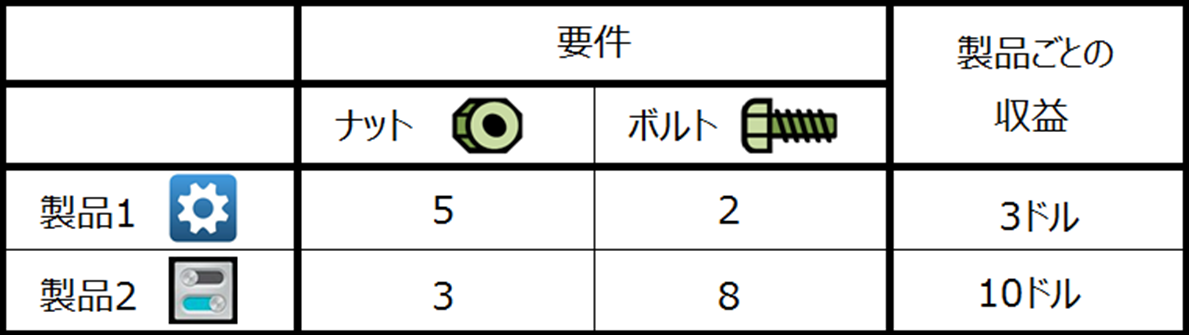

現在の在庫がナット29個、ボルト34個のとき、製品1と製品2を何個ずつ作れば利益が最大になるかを求めます。

## 定式化

最大化したいものは収益であるため、以下のような式になります。


$$\max ( 3 x_1 + 10 x_2 )$$


最大化したい利益の係数ベクトルは以下の通り。

MATLAB の最適化関数の既定は「最小化」であるため、係数にマイナスを付けることで最大化問題を解きます。

f = [-3 -10];

整数になる係数を指定します。

intcon = 1:2;

ナットとボルトの総数には以下のような制約があります。


$$2x_1 + 8x_2 \leq 34 \\
5x_1 + 3 x_2 \leq 29$$


左辺の係数を行列A、右辺をベクトルbとして定義します。

A = [2 8; 5 3];
b = [34; 29];

上限下限を0, 10に設定しておきます。

lb = zeros(2,1);
ub = ones(2,1)*10;

intlinprog 関数を使って解を求めます。

[x,fval] = intlinprog(f,intcon,A,b,[],[],lb,ub);

LP:                Optimal objective value is -44.411765.                                           

Cut Generation:    Applied 1 Gomory cut.                                                            
                   Lower bound is -43.000000.                                                       
                   Relative gap is 0.00%.                                                          

Optimal solution found.

Intlinprog stopped at the root node because the objective value is within a gap tolerance of the optimal value, options.AbsoluteGapTolerance = 0 (the default value). The intcon variables are integer within tolerance, options.IntegerTolerance = 1e-05 (the default value).


ナット、ボルトそれぞれを使って製品1と製品2をそれぞれ何個作ればよいかが求まっています。

製品1は1つ、製品2は4つで、その時の利益が$43となります。

x

x =     1.0000
    4.0000

fval

fval = -43